# Processing wind data and compute energy

Load winfarm data

load('data/windfarms_processed.mat', 'tim')

## Interpolate wind data at windfarm location

### Load wind data

Wind data is downloaded from[10.24381/cds.adbb2d47](https://doi.org/10.24381/cds.adbb2d47), with the 10m and 100m u and v component of wind.

file='./data/ECMWF/2018_srf.nc'; %ncdisp(file);
w_time = datetime('2018-01-01 00:00'):1/24:datetime('2018-12-31 23:00'); % ncread(file,'time')
w_lat=flip(double(ncread(file,'latitude')));
w_lon=double(ncread(file,'longitude'));
w_u100 = permute(flip(ncread(file,'u100'),2) , [2 1 3]); 
w_v100 = permute(flip(ncread(file,'v100'),2) , [2 1 3]);
w_u10 = permute(flip(ncread(file,'u10'),2) , [2 1 3]); 
w_v10 = permute(flip(ncread(file,'v10'),2) , [2 1 3]);

Compute the absolute windspeed value at 10 and 100m

w_100 = sqrt(w_u100.^2  + w_v100.^2);
w_10 = sqrt(w_u10.^2  + w_v10.^2);

### **Interpolate wind data**

Spatial interpolation at 100 and 10m at the windfarm location

F = griddedInterpolant({w_lat,w_lon,datenum(w_time)},w_100,'linear','nearest');
w_hundread = F(repmat(tim.Latitude,1,numel(w_time)), repmat(tim.Longitude,1,numel(w_time)), repmat(datenum(w_time),size(tim,1),1));
F = griddedInterpolant({w_lat,w_lon,datenum(w_time)},w_10,'linear','nearest');
w_ten = F(repmat(tim.Latitude,1,numel(w_time)), repmat(tim.Longitude,1,numel(w_time)), repmat(datenum(w_time),size(tim,1),1));

Vertical interpolation of the interpolated windspeed at the exact hub height of each windturbine

alpha = (log(w_hundread)-log(w_ten)) ./ (log(100)-log(10));
w_height = w_hundread .* (tim.Hub_height /100).^alpha;

### Illustration

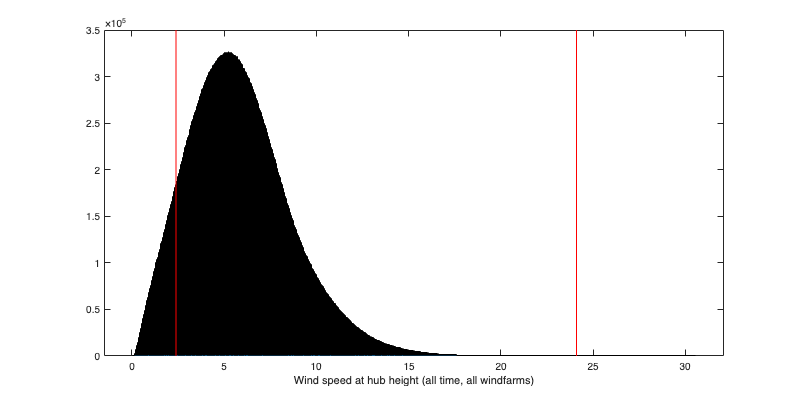

figure('position',[0 0 800 400]); box on; hold on;
histogram(w_height); xlabel('Wind speed at hub height (all time, all windfarms)')
plot([2.4 2.4],[0 3.5e5],'-r')
plot([24.1 24.1],[0 3.5e5],'-r')

% figure; plot(w_time, mean(t_height));

Windspeed at day vs night

% w_height

Variation of windspeed per day

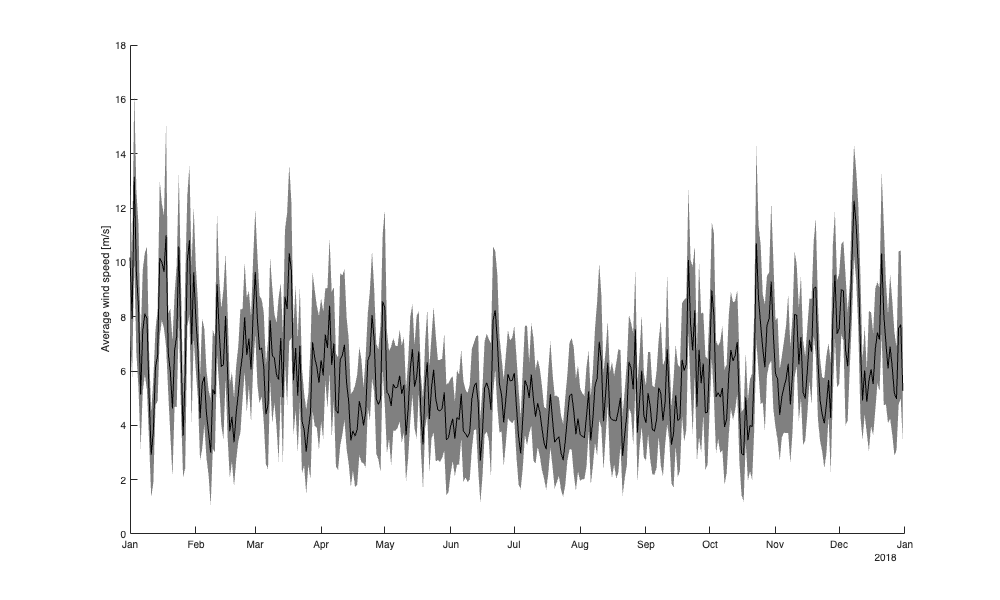

[G,w_time_day]=findgroups(dateshift(w_time,'start','day'));
w_height_mday=splitapply(@(x) nanmean(x,'all'),w_height,G);
w_height_sday=splitapply(@(x) nanstd(x,[],'all'),w_height,G);

figure('position',[0 0 1000 600]); hold on
fill([w_time_day fliplr(w_time_day)], [w_height_mday-w_height_sday fliplr(w_height_mday+w_height_sday)],[.5 .5 .5],'EdgeAlpha',0); 
plot(w_time_day, w_height_mday,'-k'); 
ylabel('Average wind speed [m/s]')

## **Compute Power**

Compute the power equivalent of each windfarm and each timestep (still on the ERA5 time resolution 1hr).

We use a small trick to match the windspeed with the equivalent power production by using the fact that the power production is set on a regular windspeed grid (`powerCurve.ws_smooth`) which is 0:0.1:35.  So, we can find for each `windspeed (t_height)`, the index in the powercurve table (tim.`power)`, using: 

wind_height_r = round(w_height,1); % round to the resolution of the windspeed 0.1
index = uint16(wind_height_r*10+1); % 0.1 resolution -> 1 resolution , and +1 to get index 0 to 1.

We can then loop through each windfarm and get the power equivalent using this index

power = nan(size(w_height));
for i_t = 1:size(w_height,1)
    power(i_t,:) = tim.powerCurve(i_t,index(i_t,:)).*tim.Number_of_turbines(i_t);
end

### Illustration

The total Power Potential is in PetaJoule (10^15 Joule or Watt/hours):

disp(sum(power*1000*60*60/1e15,'all'))

  718.6290



Visualization

[G,country]=findgroups(tim.Country);
tmp=splitapply(@sum,power,G);
[G,w_time_day]=findgroups(dateshift(w_time,'start','day'));
tmp2=splitapply(@nansum,tmp',G');

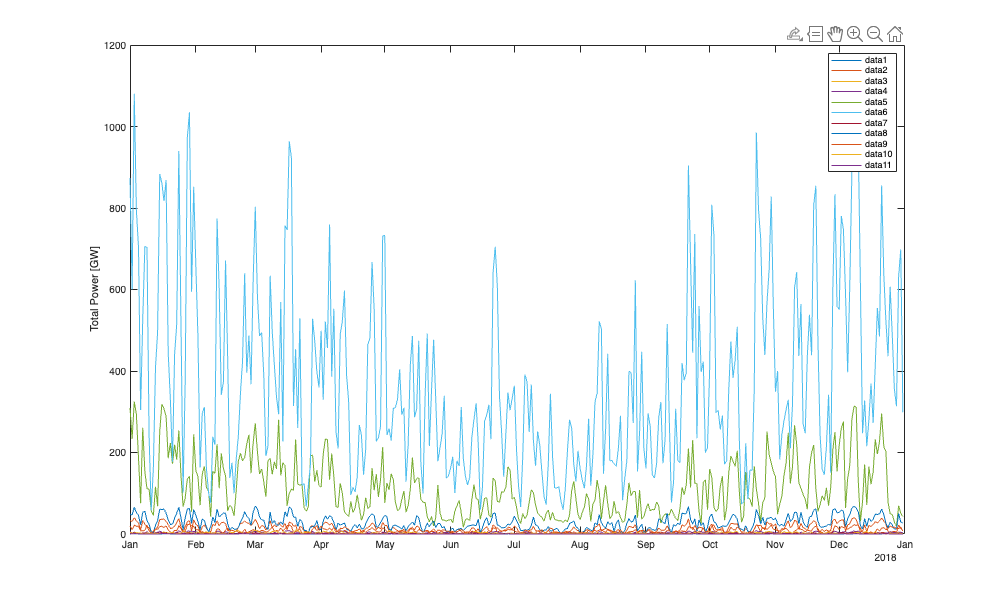

figure('position',[0 0 1000 600]);
plot(w_time_day, tmp2'*1000/1e9); ylabel('Total Power [GW]')
legend()

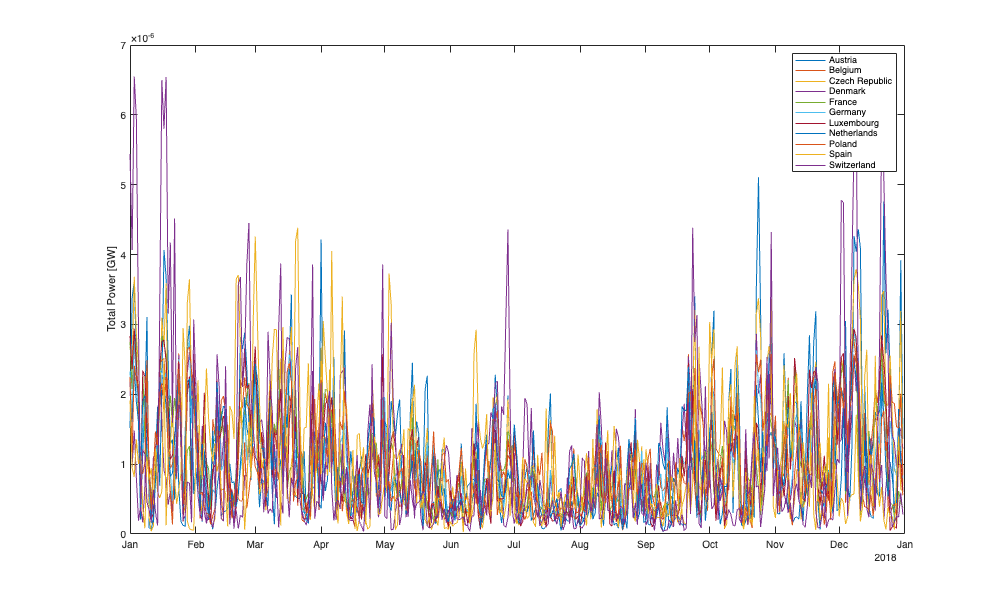

figure('position',[0 0 1000 600]);
plot(w_time_day, tmp2./mean(tmp2)*1000/1e9); ylabel('Total Power [GW]')
legend(country)

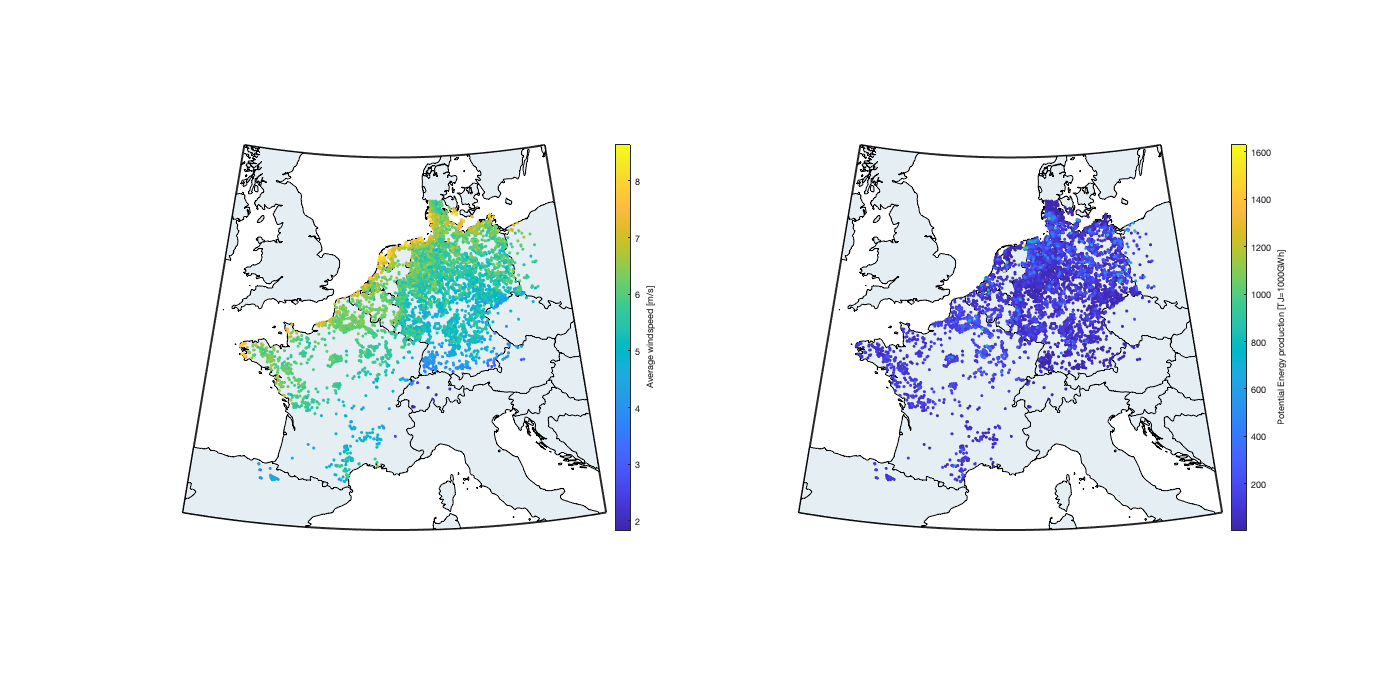

figure('position',[0 0 1400 700]);
subplot(1,2,1); hold on;
h = worldmap([min(tim.Latitude)-2 max(tim.Latitude)+2], [min(tim.Longitude)-2 max(tim.Longitude)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
% surfm(g.lat,g.lon,turbineSweptAreaMap)
scatterm(tim.Latitude,tim.Longitude,[],nanmean(w_height,2),'.');
c=colorbar; c.Label.String='Average windspeed [m/s]';
subplot(1,2,2); hold on;
h = worldmap([min(tim.Latitude)-2 max(tim.Latitude)+2], [min(tim.Longitude)-2 max(tim.Longitude)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
% surfm(g.lat,g.lon,turbineSweptAreaMap)
tmp = sum(power*1000*60*60/1e12,2); [~,id_sorted] = sort(tmp);
scatterm(tim.Latitude(id_sorted),tim.Longitude(id_sorted),[],tmp(id_sorted),'.'); % caxis([0 100]);
c=colorbar; c.Label.String='Potential Energy production [TJ=1000GWh]';

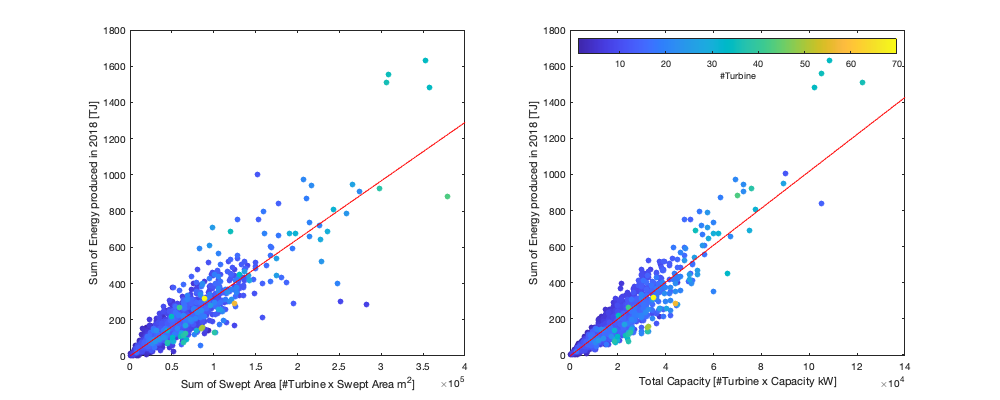

tmp = sum(power*1000*60*60/1e12,2);
[~,id]=sort(tim.Number_of_turbines);
figure('position',[0 0 1000 400]); 
subplot(1,2,1); hold on;
scatter(tim.Number_of_turbines(id).*tim.turbine_sweptArea(id),tmp(id),[],tim.Number_of_turbines(id),'filled');
l=lsline; l.Color='r'; box on
xlabel('Sum of Swept Area [#Turbine x Swept Area m^2]'); 
ylabel('Sum of Energy produced in 2018 [TJ]')
subplot(1,2,2);  hold on;
scatter(tim.Number_of_turbines(id).*tim.turbine_capacity(id),tmp(id),[],tim.Number_of_turbines(id),'filled');
l=lsline; l.Color='r'; box on
c=colorbar('north'); c.Label.String='#Turbine';
xlabel('Total Capacity [#Turbine x Capacity kW]'); 
ylabel('Sum of Energy produced in 2018 [TJ]')

## Save

time = w_time;
save('data/energy_processed.mat','time','power')